  currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc
if ~exist("AnsysWorkspace",'dir')
    mkdir('AnsysWorkspace')
end

% 参数化分析：边中跨比
Name_Parameter = 'Ratio_SideMainSpan';
Value_Parameter = [0.75];
[OriginalBridges,~,~,OriginalBridgePaths] = ParametricAnalysisLoop(Name_Parameter,Value_Parameter,...
                                           'MaxIter',30);

WorkPath = 'C:\Users\11440\Desktop\usage\Susp V.4\CableSSB-zh\test\test\AnsysWorkspace\SelfAnchored_Hybrid\MeanValue\Ratio_SideMainSpan\0.75\OriginalModel';
OutputMethod = OutputToAnsys(Bridge(),"JobName",'OrginalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath',WorkPath);
bridgeobj = OutputMethod.loadBridgeObj("ifReplaceOutputObj",true);

% 根据ANSYS求解后文件，获取内力
data_InternalForce = OutputMethod.loadResults('ResultType','InternalForce');
% 根据ANSYS求解后文件，获取位移
data_Displacement = OutputMethod.loadResults('ResultType','Displacement');
% 获取影响线


% 获取Girder的Element并排序
class_structure = 'Girder';
girders = bridgeobj.findStructureByClass(class_structure);
elems_girder = [];
for i=1:length(girders)
    girder = girders{i};
    elems_girder = [elems_girder,girder.Element];
end
sorted_elems_force = elems_girder.sortByCenterPoint('X');

sorted_elems_force =   1×690 Element 数组 - 属性:

    INode
    JNode
    KNode
    StiffnessMatrix_GlobalCoord
    Force_GlobalCoord
    Force_LocalCoord
    Section
    Material
    ElementType
    Displacement_GlobalCoord
    Num


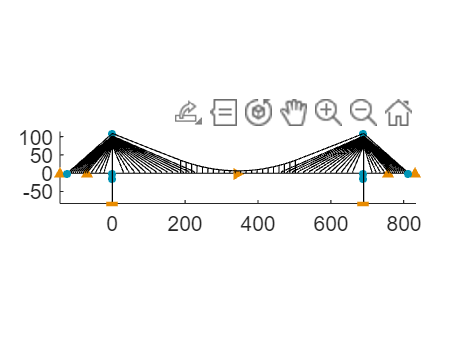

% plot整桥
fig = figure;
ax = axes;
bridgeobj.plot("Figure",fig,'Axis',ax);
view([0,-1,0])
hold(ax,'on')
% plot加劲梁部分的My
type_force = 'My';
[ANodes,BNodes,InternalForce_A,InternalForce_B] = sorted_elems_force.getBeamElementGlobalForce(class_structure,type_force);
[fig,ax] = sorted_elems_force.plotBeamElementGlobalForce(ANodes,BNodes,InternalForce_A,InternalForce_B,class_structure,...
                                     'Pattern','plot3',...
                                     'Figure',fig,...
                                     'Axis',ax,...
                                     'Scale', 20/max(abs([InternalForce_A,InternalForce_B])));
% plot加劲梁部分的Fx
type_force = 'Fx';
[ANodes,BNodes,InternalForce_A,InternalForce_B] = sorted_elems_force.getBeamElementGlobalForce(class_structure,type_force);
[fig,ax] = sorted_elems_force.plotBeamElementGlobalForce(ANodes,BNodes,InternalForce_A,InternalForce_B,class_structure,...
                                     'Pattern','plot3',...
                                     'Figure',fig,...
                                     'Axis',ax,...
                                     'Scale', 20/max(abs([InternalForce_A,InternalForce_B])));

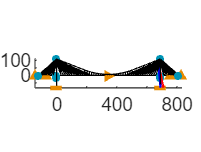

% 获取Tower的Element并排序
class_structure = 'Tower';
towers = bridgeobj.findStructureByClass(class_structure);
elems_tower1 = [towers{2}.Element];
[sorted_elems_force,index] = elems_tower1.sortByCenterPoint('Z');
% plot整桥
fig = figure;
ax = axes;
bridgeobj.plot("Figure",fig,'Axis',ax);
view([0,-1,0])
hold(ax,'on')
% plot桥塔部分的My
type_force = 'My';
[ANodes,BNodes,InternalForce_A,InternalForce_B] = getBeamElementGlobalForce(sorted_elems_force,class_structure,type_force);
[fig,ax] = plotBeamElementGlobalForce(ANodes,BNodes,InternalForce_A,InternalForce_B,class_structure,...
                                     'Pattern','plot3',...
                                     'Figure',fig,...
                                     'Axis',ax,...
                                     'Scale', 20/max(abs([InternalForce_A,InternalForce_B])));
type_displacement = 'Ux';
[nodes,Displacement] = getNodeGlobalDisplacement(sorted_elems_force,class_structure,type_displacement);
[fig,ax] = plotNodeGlobalDisplacement(nodes,Displacement,class_structure,...
                                      'Pattern','plot3',...
                                      'Figure',fig,...
                                      'Axis',ax);

function [OriginalBridges,NoCableBridges,RSCBridges,OriginalBridgePaths,NoCableBridgePaths,RSCBridgePaths] = ParametricAnalysisLoop(Name_Parameter,Values_Parameter,options)
    arguments
        Name_Parameter
        Values_Parameter
        options.SelfAnchor = true
        options.Pattern_InitPz = 'MeanValue'
        options.ifAnalyze = true
        options.MaxIter = 30
    end
    OriginalBridgePaths = cell(1,length(Values_Parameter));
    NoCableBridgePaths = cell(1,length(Values_Parameter));
    RSCBridgePaths = cell(1,length(Values_Parameter));
    OriginalBridges = [];
    NoCableBridges = [];
    RSCBridges = [];
    % 对每个参数都进行分析并提取结果
    for i=1:length(Values_Parameter)
        value = Values_Parameter(i);
        % 获取Original Model
        [original_bridge,nocable_bridge,RSC_bridge] = getOptimizedHybridBridge(Name_Parameter,value,options.SelfAnchor,options.Pattern_InitPz,options.MaxIter);
        
        % 输出构建有限元模型的 ANSYS APDL的宏文件
        original_bridge.output('ifSaveBridgeObj',true,'ifClearCollection',true);
        
        if options.ifAnalyze
            % 运行优化后的Original Model
            original_bridge.run('ComputingMode','Distributed');
            % 为每个Structure对象获取其对应的Element，存储在Structure.Element属性中
            original_bridge.OutputMethod.getAllNodesAndAllElements();
        end
    
        % 将MATLAB中的Bridge对象存储起来
        OriginalBridgePaths{i} = original_bridge.OutputMethod.WorkPath;
        NoCableBridgePaths{i} = nocable_bridge.OutputMethod.WorkPath;
        if ~isempty(RSC_bridge)
            RSCBridgePaths{i} = RSC_bridge.OutputMethod.WorkPath;
        else
            RSCBridgePaths{i} = [];
        end
        
        OriginalBridges = [OriginalBridges,original_bridge];
        NoCableBridges = [NoCableBridges,nocable_bridge];
        if ~isempty(RSCBridgePaths{i})
            RSCBridges = [RSCBridges,RSC_bridge];
        end
    end    
end

function [original_bridge,nocable_bridge,RSC_bridge] = getOptimizedHybridBridge(Name_Parameter,Value_Parameter,SelfAnchored,Pattern_InitPz,MaxIter)
    arguments
        Name_Parameter {mustBeMember(Name_Parameter,{'Ratio_SideMainSpan','Sag','Count_CrossCable'})}
        Value_Parameter
        SelfAnchored {mustBeNumericOrLogical} = true
        Pattern_InitPz {mustBeMember(Pattern_InitPz,{'RSC','MeanValue'})} = 'RSC'
        MaxIter = 30
    end

    % 建立完整的协作体系模型
    original_bridge = CableStayedSuspension_Bridge;
    original_bridge.SelfAnchored = SelfAnchored;
    if SelfAnchored
        BridgeType = 'SelfAnchored_Hybrid';
    else
        BridgeType = 'EarthAnchored_Hybrid';
    end
    original_bridge.build_Parametrically(Name_Parameter,Value_Parameter);

    [OriginalModelPath,NoCableModelPath,RSCModelPath] = newComputingFolders(BridgeType,Pattern_InitPz,Name_Parameter,Value_Parameter);

    output_method = OutputToAnsys(original_bridge,...
                    'JobName','OriginalModel',...
                    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                    'WorkPath',OriginalModelPath,...
                    'MacFilePath',fullfile(OriginalModelPath,'main.mac'),...
                    'ResultFilePath',fullfile(OriginalModelPath,'result.out'));
    original_bridge.OutputMethod = output_method;
    original_bridge.Information.Status = 'Original';
    original_bridge.Information.Type = 'Hybrid';
    original_bridge.Information.SelfAnchored = SelfAnchored;
    original_bridge.Information.Pattern_InitPz = Pattern_InitPz;
    original_bridge.Information.Name_Parameter = Name_Parameter;
    original_bridge.Information.Value_Parameter = Value_Parameter;


    % 建立无索模型（用于优化弯曲应变能，不可以直接使用ANSYS运行）
    nocable_bridge = NoCable_Bridge(original_bridge);
    nocable_bridge.build
    output_method = OutputToAnsys(nocable_bridge,...
                    'JobName','NoCableModel',...
                    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                    'WorkPath',NoCableModelPath,...
                    'MacFilePath',fullfile(NoCableModelPath,'main.mac'),...
                    'ResultFilePath',fullfile(NoCableModelPath,'result.out'));
    nocable_bridge.OutputMethod = output_method;
    nocable_bridge.getFiniteElementModel;
    nocable_bridge.OutputMethod = output_method;
    nocable_bridge.Information.Status = 'NoCable';
    
    % 优化弯曲应变能
    if strcmp(Pattern_InitPz,'RSC')
        % 建立刚性支撑连续梁模型
        RSC_bridge = RigidSupportedContinuousBeam(original_bridge);
        RSC_bridge.build
        output_method = OutputToAnsys(RSC_bridge,...
                        'JobName','NoCableModel',...
                        'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                        'WorkPath',RSCModelPath,...
                        'MacFilePath',fullfile(RSCModelPath,'main.mac'),...
                        'ResultFilePath',fullfile(RSCModelPath,'result.out'));
        RSC_bridge.OutputMethod = output_method;
        RSC_bridge.Information.Status = 'RSC';
        Pz_0 = RSC_bridge.getSupportedForce()';
        % 优化弯曲应变能
        Map_Init_Pz = containers.Map(0,Pz_0/2);
        nocable_bridge.optimBendingStrainEnergy('MaxIter',MaxIter,'DiffMinChange',1e4,'Iter',0,'Map_Iter_Pz',Map_Init_Pz);
    else
        % 以均值为初始设计竖向力，优化弯曲应变能
        RSC_bridge = Bridge.empty();
        nocable_bridge.optimBendingStrainEnergy('MaxIter',MaxIter,'DiffMinChange',1e4);
    end

    % 优化后结果
    Map_Pz = nocable_bridge.Result_Iteration.Map_Iter_Pz;
    max_iter = nocable_bridge.Iter_Optimization;
    Pz_final = Map_Pz(max_iter);
    
    % 将优化后结果恢复到Original Model中
    nocable_bridge.solveCableShape(Pz_final);
    X_Pz = nocable_bridge.XCoordOfPz;
    for i=1:length(nocable_bridge.ReplacedStayedCable)
        stayed_cable = nocable_bridge.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz_final(j);
        end
        stayed_cable.getP(P_girder_z);
    end

    % 重新设置ElementType
    elementtypes = original_bridge.ElementTypeList;
    for i=1:length(elementtypes)
        elementtype = elementtypes{i};
        if contains(class(elementtype),'Beam')
            elementtype.AdditionalNode = 1;
        end
    end
end
function [OriginalModelPath,NoCableModelPath,RSCModelPath] = newComputingFolders(BridgeType,Pattern_InitPz,Name_Parameter,Value_Parameter)
    arguments
        BridgeType {mustBeMember(BridgeType,{'SelfAnchored_Hybrid','EarthAnchored_Hybrid','SelfAnchored_Suspension','CableStayed'})}
        Pattern_InitPz {mustBeMember(Pattern_InitPz,{'RSC','MeanValue'})}
        Name_Parameter {mustBeText}
        Value_Parameter {mustBeNumeric}
    end
    if ~isfolder(fullfile(pwd,'AnsysWorkspace'))
        error('当前文件夹下不存在文件夹./AnsysWorkspace')
    else
        BridgeTypeFolder = fullfile(pwd,'AnsysWorkspace',filesep,BridgeType,filesep);
        InitPzPatternFolder = fullfile(BridgeTypeFolder,Pattern_InitPz,filesep);
        ParameterFolder = fullfile(InitPzPatternFolder,Name_Parameter,filesep);
        ParameterValueFolder = fullfile(ParameterFolder,num2str(Value_Parameter),filesep);
        OriginalModelPath = fullfile(ParameterValueFolder,'OriginalModel',filesep);
        NoCableModelPath = fullfile(ParameterValueFolder,'NoCableModel',filesep);
        RSCModelPath = fullfile(ParameterValueFolder,'RSCModel',filesep);
    end
    if ~exist(OriginalModelPath,'dir')
        mkdir(OriginalModelPath)
    end
    if ~exist(NoCableModelPath,'dir')
        mkdir(NoCableModelPath)
    end
    if ~exist(RSCModelPath,'dir')
        mkdir(RSCModelPath)
    end
end